clear;clc
L = 12; % Region size
hbar = 1; % Reduced Planck's constant
m = 1;    % Electron mass
% Define the size of the region and the number of points for discretization
N = 5*10^5;   % Number of points for discretization
N_state=10;   % Number of states from vacuum
dx = L / N; % Discretization step
x = linspace(-L/2, L/2, N);
%%  Define the potential function
%%%%%%%%%%%%%%%%%%%%%%%%%%
% Vpar.Omega=2*pi; %Hz
% Vpar.kappa=2*pi*10^6; %Hz
% Vpar.Delta=2*pi*10^4; %Hz
% Vpar.g=2*pi*18.75;
%%%%%%%%%%%%%%%%%%%%%%%%
Vpar.Omega=1.5*10^5*pi; %Hz
Vpar.kappa=2*pi*1.8*10^5; %Hz
Vpar.Delta=2*pi*10^2; %Hz
Vpar.g=2*pi*1875;
Vpar.nc=Vpar.Omega*(4*Vpar.Delta^2+Vpar.kappa^2)/(16*Vpar.g^2*Vpar.Delta);

%%%%%%%%%%%%%%%%%%%%%%%%%%%
alpha_V=1.0029;%%17900*0.9935715 splitiing happens for alpha_V=1
Vpar.n=Vpar.nc*alpha_V;
V=1/2*Vpar.Omega*x.^2+...
    Vpar.n*(Vpar.Delta^2+Vpar.kappa^2/4)/(Vpar.kappa/2).*...
    (   atan( (Vpar.Delta+Vpar.g*x)/(Vpar.kappa/2)   )   ...
    +   atan( (Vpar.Delta-Vpar.g*x)/(Vpar.kappa/2)   )    );  %(1-10^-11)


d2dx2 = sparse([[1:N],[2:N],[1:N-1]],   [[1:N],[1:N-1],[2:N]],...
    [[-2*ones(1,N),1*ones(1,N-1),1*ones(1,N-1)]],N,N); %-2*diag(ones(1, N)) + diag(ones(1, N-1), 1) + diag(ones(1, N-1), -1);
d2dx2 = d2dx2 / dx^2;
T = -hbar^2 / (2*m) * d2dx2;

% Construct the potential energy matrix V
V_matrix = sparse([1:N],[1:N],V,N,N);   %diag(V);

% Form the Hamiltonian matrix H = T + V
H = T + V_matrix;


tic
% Solve the eigenvalue problem for the Hamiltonian matrix
[eigenfunctions, eigenvalues] =  eigs(H,N_state,min(V));%,'Tolerance' ,'Tolerance',1e-10
toc

Elapsed time is 1.808810 seconds.


eigenfunctions'*eigenfunctions-eye(10)

ans = 1.0e-14 *

   -0.0555   -0.0305    0.0074    0.0341   -0.0161    0.0421    0.0088    0.0060   -0.0071    0.0081
   -0.0305         0   -0.0082    0.0195   -0.0010   -0.0038    0.0032    0.0153   -0.0197    0.0230
    0.0074   -0.0082   -0.0222   -0.1382    0.0159   -0.0052   -0.0358   -0.0708    0.0313   -0.0434
    0.0341    0.0195   -0.1382   -0.0444   -0.0423    0.0277    0.0485    0.0654   -0.0044   -0.0055
   -0.0161   -0.0010    0.0159   -0.0423   -0.0222    0.3739   -0.0515   -0.0324   -0.0013   -0.0109
    0.0421   -0.0038   -0.0052    0.0277    0.3739   -0.0333    0.0342    0.0459   -0.0460    0.0270
    0.0088    0.0032   -0.0358    0.0485   -0.0515    0.0342   -0.0444   -0.1349   -0.0543    0.0735
    0.0060    0.0153   -0.0708    0.0654   -0.0324    0.0459   -0.1349   -0.1110   -0.1093    0.1061
   -0.0071   -0.0197    0.0313   -0.0044   -0.0013   -0.0460   -0.0543   -0.1093         0    0.1102
    0.0081    0.0230   -0.0434   -0.0055   -0.0109    0.0270    0.0735    

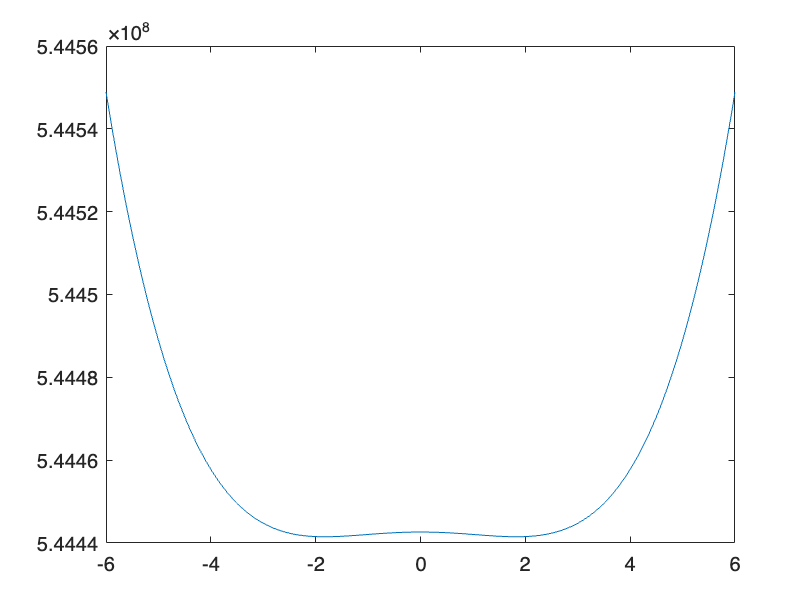

eigenvalues=diag(eigenvalues);
%%
eigenfunctions=Eigenfun_Reorder(eigenfunctions,eigenvalues);
plot(x,V)
xlim([-L,L]/2)

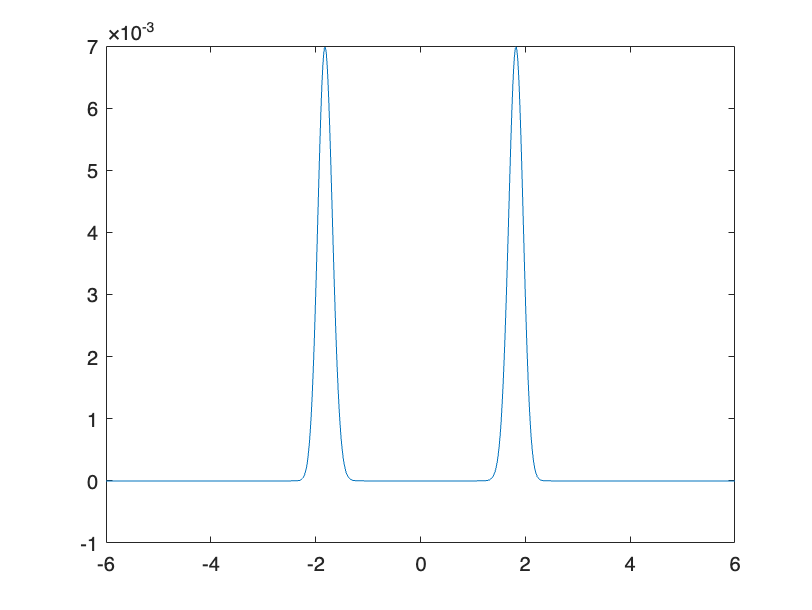

plot(x,eigenfunctions(:,1))
xlim([-L,L]/2)

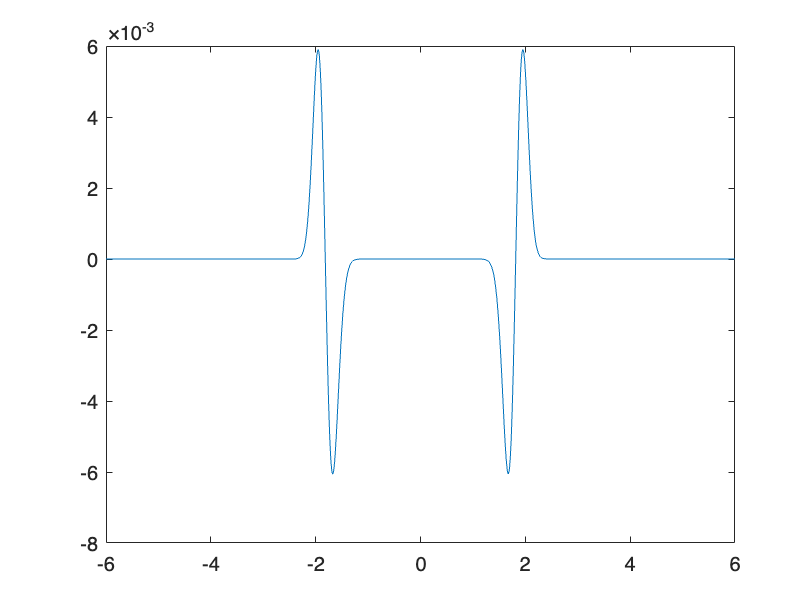

%plot(x,eigenfunctions(:,2))
plot(x,eigenfunctions(:,3))

%plot(x,eigenfunctions(:,4))

%plot(eigenvalues-eigenvalues(1))